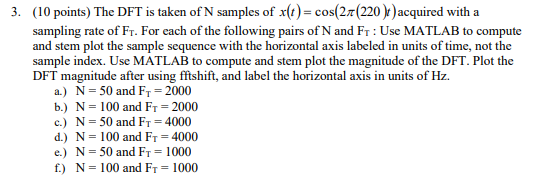

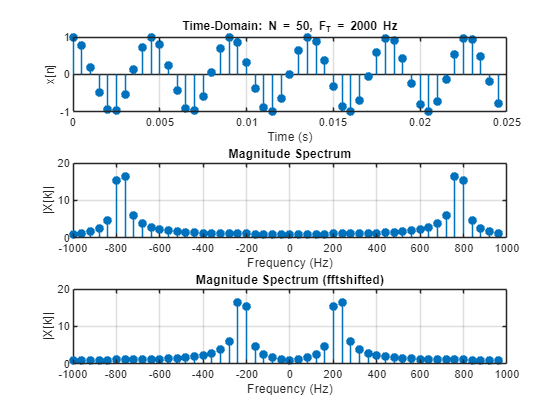

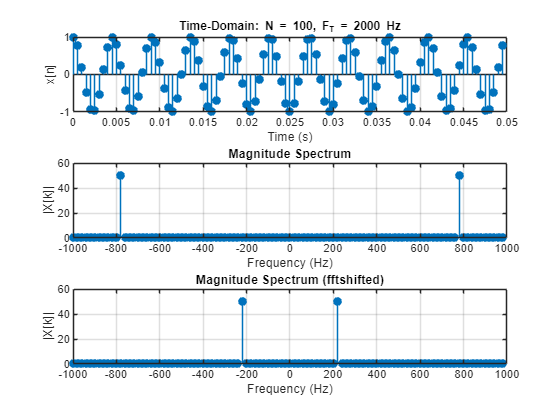

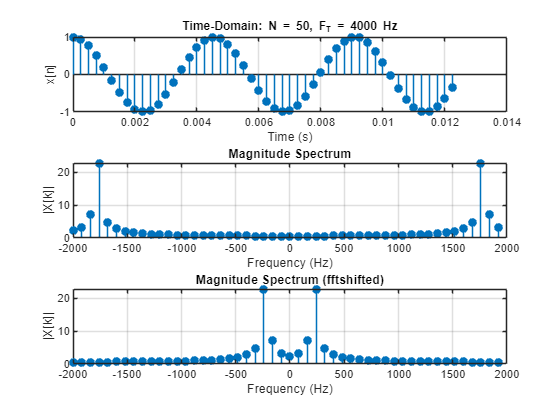

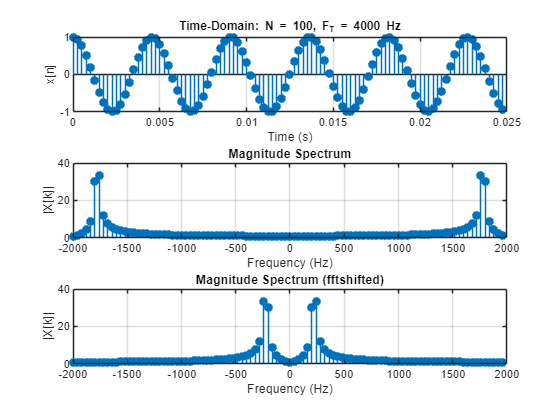

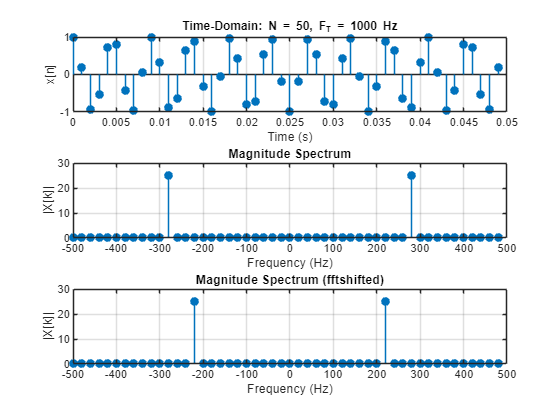

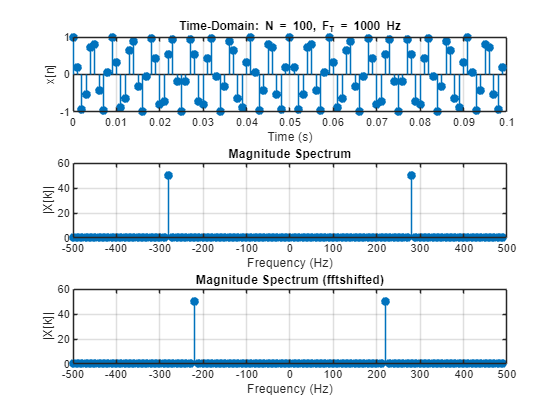

FT= [2000,2000,4000,4000,1000,1000];
N= [50,100,50,100,50,100];
for i=1:6
    T = 1 / FT(i);                   
    t = (0:N(i)-1) * T;              
    x = cos(2*pi*220 * t);        

    X = fft(x);
    Xshift = fftshift(X);
    f = (-N(i)/2:N(i)/2-1) * (FT(i) / N(i));  

    figure;
    subplot(3,1,1);
    stem(t, x, 'filled');
    xlabel('Time (s)');
    ylabel('x[n]');
    title(sprintf('Time-Domain: N = %d, F_T = %d Hz', N(i), FT(i)));
    grid on;

    subplot(3,1,2);
    stem(f, abs(X), 'filled');
    xlabel('Frequency (Hz)');
    ylabel('|X[k]|');
    title('Magnitude Spectrum');
    grid on;

    subplot(3,1,3);
    stem(f, abs(Xshift), 'filled');
    xlabel('Frequency (Hz)');
    ylabel('|X[k]|');
    title('Magnitude Spectrum (fftshifted)');
    grid on;
end

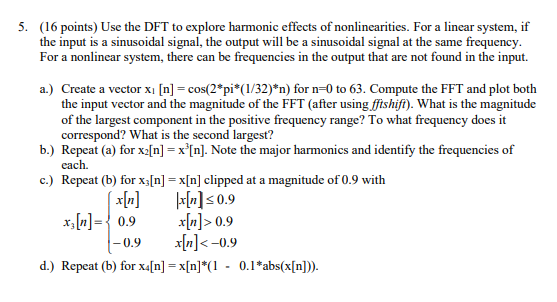

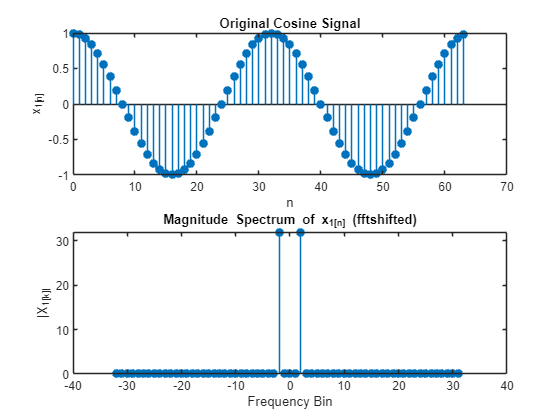

n = 0:63;
x1 = cos(2*pi*(1/32)*n);

X1 = fftshift(fft(x1));
f = (-32:31);  

figure;
subplot(2,1,1);
stem(n, x1, 'filled');
xlabel('n'); ylabel('x_1[n]');
title('Original Cosine Signal');

subplot(2,1,2);
stem(f, abs(X1), 'filled');
xlabel('Frequency Bin');
ylabel('|X_1[k]|');
title('Magnitude Spectrum of x_1[n] (fftshifted)');

**Magnitude of largest component is at bin 2 (freq=2Hz) and is 32. This is because the largest is N/2 when no leakage (which is what we see) and N=64. The second largest is also 32 at bin -2, but everything else is 0.**

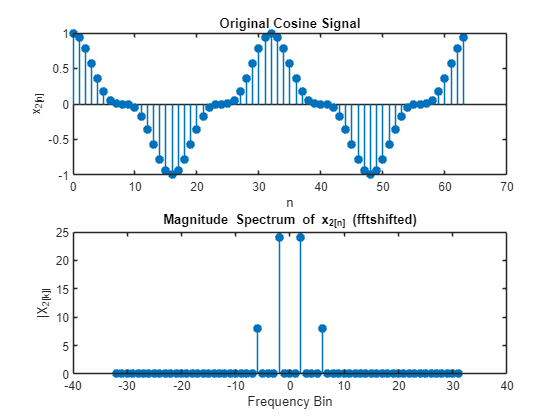

x2=x1.^3;

X2 = fftshift(fft(x2));
f = (-32:31);  

figure;
subplot(2,1,1);
stem(n, x2, 'filled');
xlabel('n'); ylabel('x_2[n]');
title('Original Cosine Signal');

subplot(2,1,2);
stem(f, abs(X2), 'filled');
xlabel('Frequency Bin');
ylabel('|X_2[k]|');
title('Magnitude Spectrum of x_2[n] (fftshifted)');

**I see harmonics of amplitude 8 at -6 and 6 Hz, and 24 at -2 and 2Hz.**

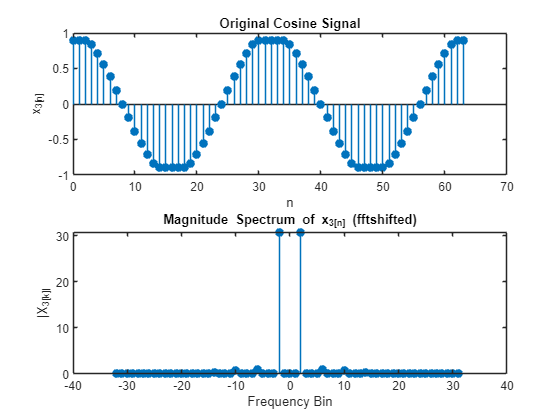

x3=x1;
x3(x1 > 0.9)  = 0.9;
x3(x1 < -0.9) = -0.9;

X3 = fftshift(fft(x3));
f = (-32:31);  

figure;
subplot(2,1,1);
stem(n, x3, 'filled');
xlabel('n'); ylabel('x_3[n]');
title('Original Cosine Signal');

subplot(2,1,2);
stem(f, abs(X3), 'filled');
xlabel('Frequency Bin');
ylabel('|X_3[k]|');
title('Magnitude Spectrum of x_3[n] (fftshifted)');

**Harmonics of decreasing value at bins +- 6,10,14,18,22,26,30. The major one is still at +-2.**

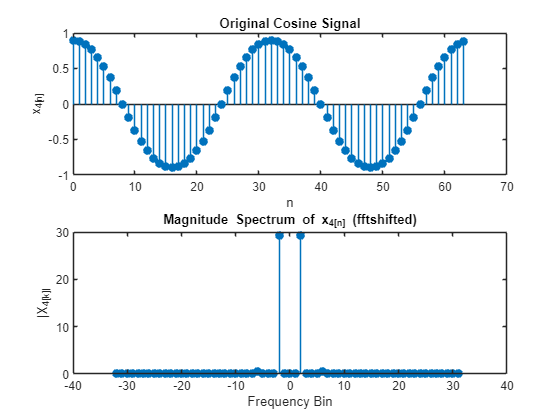

x4= x1.*(1 - 0.1 * abs(x1));

X4 = fftshift(fft(x4));
f = (-32:31);  

figure;
subplot(2,1,1);
stem(n, x4, 'filled');
xlabel('n'); ylabel('x_4[n]');
title('Original Cosine Signal');

subplot(2,1,2);
stem(f, abs(X4), 'filled');
xlabel('Frequency Bin');
ylabel('|X_4[k]|');
title('Magnitude Spectrum of x_4[n] (fftshifted)');

**Harmonics at +-2 and small ones at +-6.**